## Modal Analysis for ME 599

## Bookkeeping

By Connor Getz Created: 04/05/2024 Last Editted: 05/11/2024

## Notes

- All Trig is radian based

## 1. Givens and Inputs

% Givens
clear, clc, close all;
% NOTE: Sea Level US Standard Atmosphere means 15C, ~101.3kPa (abs), 0% Humidity
k = 12000;              % [N/m] Fluid Stiffness
L = 1.130;              % [m] Length of the Enclosure
rho = 1.225;            % [kg/m^3] Density of air at NC, Dry Air
Area = 0.02483;         % [m^2] Cross-sectional Area of the Enclosure
P_0 = 0.02;             % [m] Driver Offset
x_0 = 0;                % [m] Initial Position
v_0 = 0;                % [m/s] Initial Velocity
F_0 = 1;                % [N] Force Imparted by the Driver
e = 2.71828;            % [-] Euler's Constant
C = 340.3;                % [m/s] Speed of Sound at NC, Dry Air
E = (C^2)*rho;          % [Pa] Bulk Modulus for Air

% Input
n = 5;

## 2. Space Allocation

Ref = zeros(n,1);
C_ortho = zeros(n,n);
Diag = zeros(n,1);
m_n = zeros(n,n);
k_n = zeros(n,n);
m_dn = zeros(n,1);
k_dn = zeros(n,1);
Omega_nn = zeros(n,1);
Zeta_n = zeros(n,1);

## 3. Evaluating the Characteristic Equation

myfun = @(x) x*cot(x) + ((k*L)/(E*Area));
fun = @(x) myfun(x);
Lambda_n(1,1) = fzero(myfun,0.5);
for i = 2:n
    myfun = @(x) x*cot(x) + ((k*L)/(E*Area));
    Lambda_n(i,1) = fzero(myfun,Lambda_n(i-1,1)+(pi+0.04445176009775278838653811*i));
    Lambda_n(i,2) = Lambda_n(i,1)*2/pi; % For reference

Solved for iteratively to best represent the next root. This function becomes unstable after root 35 and considers asymptotes to be roots. This can be seen in Figure 2: Root Value versus Root Number below.

    Ref(i,1) = Lambda_n(i-1,1)+(pi+0.04445176009775278838653811*i);

    Ref(i,2) = Lambda_n(i-1,1)+pi;

The Ref(i,j) matrix holds the alternative solver guesses used to find the zeros to the Characteristic Equation

end

## 4. Proof of Trigonometric Orthogonality/Solving for Mass and Stiffness Matrices

for i = 1:n
    for j = 1:n
        % To match solution functions in proof
        if  i == j
            C_ortho(i,j) = -((L*(sin(2*Lambda_n(i,1))-2*Lambda_n(i,1)))/(4*Lambda_n(i,1)));
            %C_ortho(i,j) = (L*sin((2*Lambda_n(i,1)*P_0)/L) - 2*Lambda_n(i,1)*P_0 - L*sin(2*Lambda_n(i,1)) + 2*Lambda_n(i,1)*L)/(4*Lambda_n(i,1));
        else
            C_ortho(i,j) = 0.5*((L/(Lambda_n(i,1)-Lambda_n(j,1)))*sin(Lambda_n(i,1)-Lambda_n(j,1))- ...
            (L/(Lambda_n(i,1)+Lambda_n(j,1)))*sin(Lambda_n(i,1)+Lambda_n(j,1)));
        end

Lambda_n is the matrix housing all of the possible values for the integral of the two sine functions. As expected the diagonal of the matrix is the only portion of the matrix that is not zero. Due to the root function becoming unstable, this function is likewise not accurate beyond n = 35.

To Eliminate Solver Error

        if  1*10^-12 > C_ortho(i,j)
            C_ortho(i,j) = 0;
        else
            C_ortho(i,j) = C_ortho(i,j);
        end
        % Establishing mass and stiffness matrices
        m_n(i,j) = C_ortho(i,j); % (cos(Lambda_n(i,1))-1);
        k_n(i,j) = (((Lambda_n(i,1)/L)^2)*C_ortho(i,j)*(C^2)); % (cos(Lambda_n(i,1))-1);
        %C_PDE(i,1) = (-L/rho)*(cos((Lambda_n(i,1)*P_0)/L)-cos(Lambda_n(i,1)));
        %C_PDE(i,1) = (-1/rho)*cos((Lambda_n(i,1)*(P_0))/L);
        C_PDE(i,1) = (1/rho);
    end
end
for i = 1:n
    Diag(i,1) = C_ortho(i,i);
    m_dn(i,1) = m_n(i,i);
    k_dn(i,1) = k_n(i,i);
end

## 5. Experimentally Defined Damping


Omega_Experimental = [130, 140, 260, 290, 390, 420, 510, 580, 670, 710;...% Level 1
                      120, 130, 250, 285, 390, 420, 510, 570, 650, 695;...% Level 2
                      125, 145, 240, 285, 370, 420, 510, 570, 640, 670;...% Level 3
                      130, 145, 240, 280, 350, 410, 490, 560, 620, 690;...% Level 4
                      130, 140, 240, 280, 370, 440, 495, 580, 760, 830;...% Level 5
                      120, 135, 240, 280, 340, 430, 490, 580, 605, 680;...% Level 6
                      120, 140, 240, 285, 370, 430, 490, 560, 610, 660;...% Level 7
                      120, 135, 230, 280, 320, 460, 490, 570, 605, 660;...% Level 8
                      115, 130, 220, 280, 320, 440, 470, 560, 600, 660;...% Level 9
                      110, 130, 210, 290, 315, 440, 460, 570, 610, 680;...% Level 10
                      110, 130, 205, 295, 315, 430, 460, 560, 605, 680;...% Level 11
                      110, 125, 230, 295, 310, 420, 470, 595, 605, 680;...% Level 12
                      110, 130, 230, 300, 310, 430, 460, 590, 605, 680;...% Level 13
                      110, 135, 230, 295, 315, 430, 450, 570, 600, 690]; % Level 14 - Picked Points from Experiemtnal Real Graph

for q = 1:14
for i = 1:n
    j = (i-1)*2;
    Omega_nn(i,1) = sqrt(k_n(i,i)/m_n(i,i));
    Omega_nCheck(i,1) = (Lambda_n(i,1)*C)/L; 
    Omega_nHz(i,1) = Omega_nn(i,1)/6.2831853;
    Zeta_n(i,q) = ((Omega_Experimental(q,j+2)-Omega_Experimental(q,j+1))/(2*Omega_nHz(i,1)));
    c_n = (2*Zeta_n(i,q)*Omega_nn)/m_n(i,i);
end

if Zeta_n(1,1) >= 1 % Should be the largest Zeta value
    disp('Warning: Impossible Zeta')
end

## 6. Establishing the Final EOM

### Establishing ODE Constants

for i = 1:n
    B_ODE(i,1) = (k_n(i,i)/m_n(i,i));
    A_ODE(i,1) = 2*Zeta_n(i,q)*Omega_nn(i,1);
    C_ODE(i,1) = C_PDE(i,1)/m_n(i,i);
end

### Identifying the ODE's Roots

for i = 1:n
    Root_ODE(i,1) = 0.5*(-A_ODE(i,1)+sqrt((A_ODE(i,1)^2)-4*B_ODE(i,1)) );
end

Compare to Experimental Response

% Corresponding Frequency
F_all = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Frequency');
% 0 grams of Damping
T_0P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.000.W.01');
% 110 grams of Damping
T_110P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.110.W.01');
% 250 grams of Damping
T_250P = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','SP1.250.W.01');
% Data for Visuals
Scatter = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Scatter');
DfV = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','DataforVisuals');
Ar1 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area1');
Ar2 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area2');
Ar3 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area3');
Ar4 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area4');
Ar5 = readmatrix('Data_Processing_Excel_to_MATLAB.xlsx','sheet','Area5');

### Following Inmann Textbook Solution

k_driver = 0.00071;          % [m/N] Mechanical Compliance of the Driver Suspension (ND140-4 Manual)
S_d = 0.00866;               % [m^2] Surface Area of the Driver
P_ref = 2*10^(-4);           % [Pa] Reference Pressure used for Decibel Calculation (Engineering Toolbox)

for w = 20:20000
    Omega_Hz = w;             % [Hz] Forcing Function Frequency
    Omega = Omega_Hz*6.2831853;    % [Rad/s] Forcing Function Frequency
    %Omega = Omega_nn(1, 1)+0.001;
    
    for i = 1:n
        f_0(i,1) = (F_0*C_ODE(i,1)); % Corrected Force
        A_sol(i,1) = real(Root_ODE(i,1)); % w_d
        B_sol(i,1) = imag(Root_ODE(i,1)); % -Zeta_n*Omega_nn
        Theta_n(i,1) = atan((x_0*A_sol(i,1))/((Omega_nn(i,1)^2)-(Omega^2)));
        X_n(i,1) = (f_0(i,1)/C_ortho(i,i))/sqrt((Omega_nn(i,1)^2-Omega^2)^2 +(2*Zeta_n(i,q)*Omega_nn(i,1)*Omega)^2);
        Phi_n(i,1) = atan((A_sol(i,1)*(x_0-X_n(i,1)*cos(Theta_n(i,1))))/(v_0+(x_0-X_n(i,1)*cos(Theta_n(i,1)))*Zeta_n(i,q)*Omega_nn(i,1)-Omega*X_n(i,1)*sin(Theta_n(i,1))));
        A_n(i,1) = (x_0 - X_n(i,1)*cos(Theta_n(i,1)))/(sin(Phi_n(i,1)));
    end
    t = 0.05:0.00001:0.2;
    Y_n1 = A_n(1,1).*(e.^(-B_sol(1,1).*t)).*sin(A_sol(1,1).*t+Phi_n(1,1))+X_n(1,1).*cos(Omega.*t-Theta_n(1,1));
    Y_n2 = A_n(2,1).*(e.^(-B_sol(2,1).*t)).*sin(A_sol(2,1).*t+Phi_n(2,1))+X_n(2,1).*cos(Omega.*t-Theta_n(2,1));
    Y_n3 = A_n(3,1).*(e.^(-B_sol(3,1).*t)).*sin(A_sol(3,1).*t+Phi_n(3,1))+X_n(3,1).*cos(Omega.*t-Theta_n(3,1));
    Y_n4 = A_n(4,1).*(e.^(-B_sol(4,1).*t)).*sin(A_sol(4,1).*t+Phi_n(4,1))+X_n(4,1).*cos(Omega.*t-Theta_n(4,1));
    Y_n5 = A_n(5,1).*(e.^(-B_sol(5,1).*t)).*sin(A_sol(5,1).*t+Phi_n(5,1))+X_n(5,1).*cos(Omega.*t-Theta_n(5,1));
    Y_total = Y_n1 + Y_n2 + Y_n3 + Y_n4 + Y_n5;
    Dis1(w,1) = abs(max(Y_n1));
    Dis2(w,1) = abs(max(Y_n2));
    Dis3(w,1) = abs(max(Y_n3));
    Dis4(w,1) = abs(max(Y_n4));
    Dis5(w,1) = abs(max(Y_n5));
    Dis(w,1) = abs(max(Y_total));
    Omega_Tracker(w,1) = w;

    F_Applied = Dis(w,1)/k_driver;                 % [N] Approximated force applied by the driver
%    P_Applied(w,1) = F_Applied/S_d;                     % [Pa] Pressure wave created by the driver
    P_Applied(w,1) = E*(abs(((Lambda_n(1,1)/L)*cos(Lambda_n(1,1)))*Dis1(w,1)) + abs(((Lambda_n(2,1)/L)*cos(Lambda_n(2,1)))*Dis2(w,1)) + abs(((Lambda_n(3,1)/L)*cos(Lambda_n(3,1)))*Dis3(w,1)) + abs(((Lambda_n(4,1)/L)*cos(Lambda_n(4,1)))*Dis4(w,1)) + abs(((Lambda_n(5,1)/L)*cos(Lambda_n(5,1)))*Dis5(w,1)));




    SPL(w,q) = 10*log10((P_Applied(w,1)^2)/(P_ref^2));    % [dB] Sound Pressure Level created at the driver in decibels

%     if  SPL(w,1) < 0
%         break % Exit loop because of error
%     end
end
end

## Data Visualization

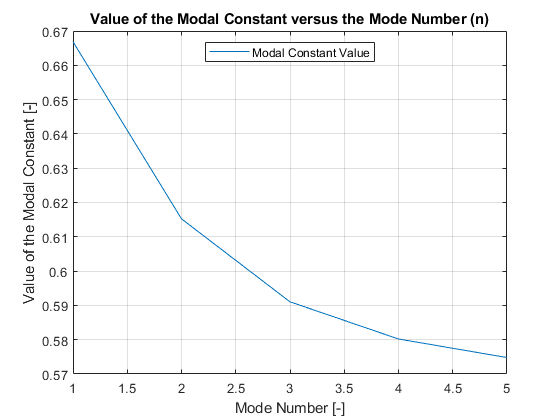

x_testplot = 1:n;
% Figure 1
f1 = figure('Name','Figure 1: Modal Constants','NumberTitle','off');
plot(x_testplot, Diag(:,1))
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([100 116]);
%xlim([33 37]);
title('Value of the Modal Constant versus the Mode Number (n)');
ylabel('Value of the Modal Constant [-]');
xlabel('Mode Number [-]');
legend('Modal Constant Value', 'location','N')

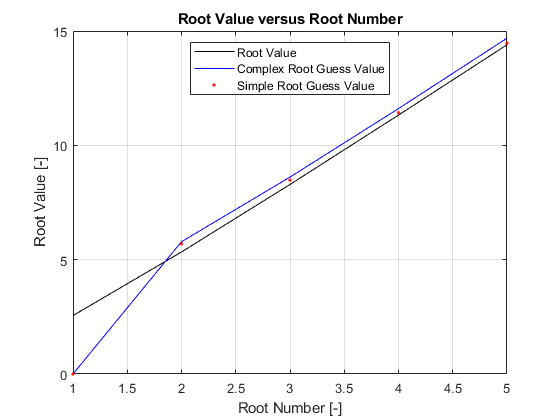

% Figure 2
f2 = figure('Name','Figure 2: Root Value versus Root Number', ...
    'NumberTitle','off');
plot(x_testplot, Lambda_n(:,1), "k", x_testplot, Ref(:,1), "b", ...
    x_testplot, Ref(:,2), ".r")
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
%ylim([100 116]);
%xlim([33 37]);
title('Root Value versus Root Number');
ylabel('Root Value [-]');
xlabel('Root Number [-]');
legend('Root Value','Complex Root Guess Value', ...
    'Simple Root Guess Value','location','N')

Figure 5

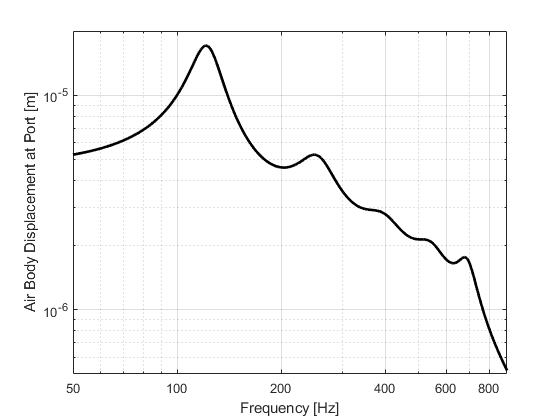

% Figure 5
f5 = figure('Name','Figure 5: Displacement Frequency Response', ...
    'NumberTitle','off');
loglog(Omega_Tracker(:,1), Dis(:,1),'k', 'LineWidth', 2);
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([0.0000005 0.00002]);
xlim([50 900]);
%Adds title
xticks([50 100 200 400 600 800 1000 1500 2000])
xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000'})
%title('Displacement Response Graph');
xlabel('Frequency [Hz]');
ylabel('Air Body Displacement at Port [m]');

Figure 6

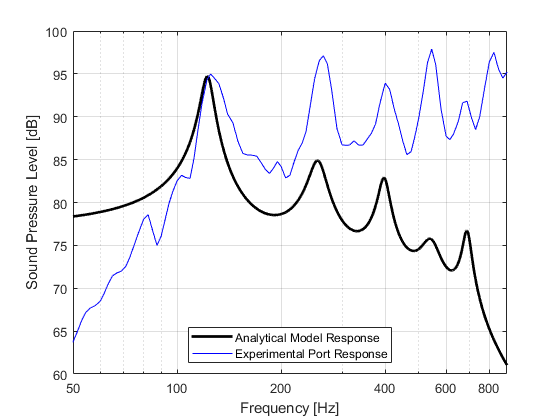

% Figure 6
f6 = figure('Name','Figure 6: Total Frequency Response', ...
    'NumberTitle','off');
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
semilogx(F_all, T_0P(:,21), 'b');
%loglog(F_all, T_0(:,21), 'r');
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([60 100]);
xlim([50 900]);
%Adds title
xticks([50 100 200 400 600 800 1000 1500 2000])
xticklabels({'50', '100', '200', '400', '600', '800', '1000', '1500', '2000'})
%title('Total Frequency Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Analytical Model Response', 'Experimental Port Response','location','S')

Figure 7

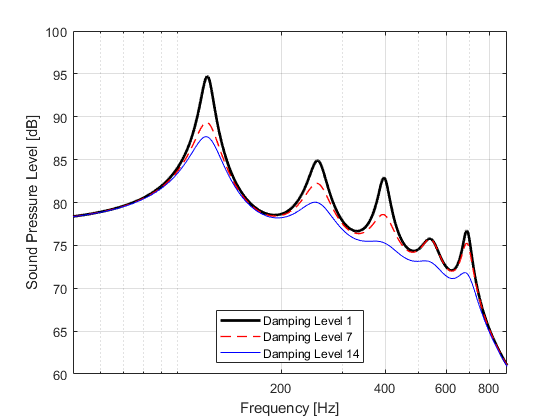

% Figure 7
f7 = figure('Name','Figure 7: Total Frequency Response', ...
    'NumberTitle','off');
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
% loglog(Omega_Tracker(:,1), SPL(:,2),'r');
% loglog(Omega_Tracker(:,1), SPL(:,3),'b');
% loglog(Omega_Tracker(:,1), SPL(:,4),'c');
% loglog(Omega_Tracker(:,1), SPL(:,5),'y');
% loglog(Omega_Tracker(:,1), SPL(:,6),'m');
 semilogx(Omega_Tracker(:,1), SPL(:,7),'r--', 'LineWidth', 1);
% loglog(Omega_Tracker(:,1), SPL(:,8),'r--');
% loglog(Omega_Tracker(:,1), SPL(:,9),'b--');
% loglog(Omega_Tracker(:,1), SPL(:,10),'c--');
% loglog(Omega_Tracker(:,1), SPL(:,11),'y--');
% loglog(Omega_Tracker(:,1), SPL(:,12),'m--');
% loglog(Omega_Tracker(:,1), SPL(:,13),'k');
 semilogx(Omega_Tracker(:,1), SPL(:,14),'b');
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([60 100]);
xlim([50 900]);
%Adds title
xticks([20 200 400 600 800 1000 1500 2000])
xticklabels({'20','200', '400', '600', '800', '1000', '1500', '2000'})
%title('Damped SPL Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
legend('Damping Level 1', 'Damping Level 7', 'Damping Level 14', 'location','S')

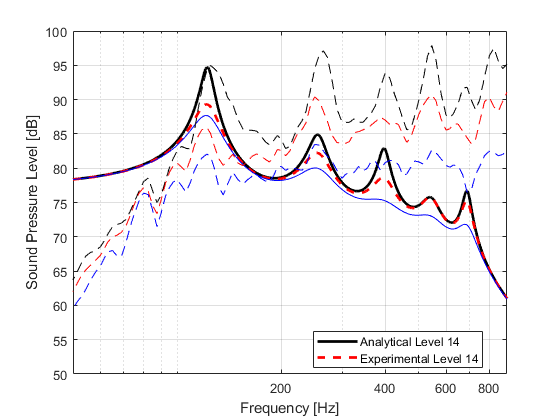

% Figure 8
f7 = figure('Name','Figure 8: MultiLevel Comparison', ...
    'NumberTitle','off');
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
semilogx(Omega_Tracker(:,1), SPL(:,7),'r--', 'LineWidth', 2);
semilogx(Omega_Tracker(:,1), SPL(:,14),'b');
semilogx(F_all, T_0P(:,21), 'k--');
semilogx(F_all, T_110P(:,21), 'r--');
semilogx(F_all, T_250P(:,21), 'b--');
hold off
%Adds grid to graph
grid on
%Adds box to outside of graph
box on
%Limit for axis
ylim([50 100]);
xlim([50 900]);
%Adds title
xticks([20 200 400 600 800 1000 1500 2000])
xticklabels({'20','200', '400', '600', '800', '1000', '1500', '2000'})
%title('Damped SPL Response Graph');
xlabel('Frequency [Hz]');
ylabel('Sound Pressure Level [dB]');
%legend('Analytical Level 1', 'Analytical Level 7', 'Analytical Level 14','Experimental Level 1', 'Experimental Level 7', 'Experimental Level 14', 'location','best')
legend('Analytical Level 14','Experimental Level 14', 'location','best')

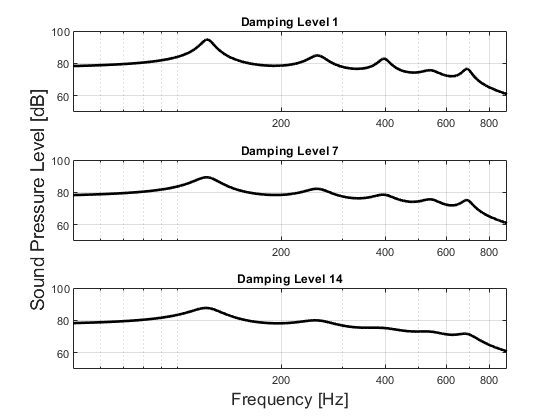

% Figure 11
f11 = figure('Name','Figure 11: MultiLevel Comparison', ...
    'NumberTitle','off');
tiledlayout(3,1);
% Plot 1
nexttile
semilogx(Omega_Tracker(:,1), SPL(:,1),'k', 'LineWidth', 2);
hold on
% semilogx(F_all, T_0P(:,21), 'k--');
hold off
grid on
box on
ylim([50 100]);
xlim([50 900]);
xticks([20 200 400 600 800 1000 1500 2000])
xticklabels({'20','200', '400', '600', '800', '1000', '1500', '2000'})
title('Damping Level 1')
% lgd = legend('Analytical Results','Experimental Data', 'location','S');
% lgd.NumColumns = 2;
% Plot 2
nexttile
semilogx(Omega_Tracker(:,1), SPL(:,7),'k', 'LineWidth', 2);
hold on
% semilogx(F_all, T_110P(:,21), 'k--');
hold off
grid on
box on
ylim([50 100]);
xlim([50 900]);
xticks([20 200 400 600 800 1000 1500 2000])
xticklabels({'20','200', '400', '600', '800', '1000', '1500', '2000'})
ylabel('Sound Pressure Level [dB]','FontSize',14);
title('Damping Level 7')
% lgd = legend('Analytical Results','Experimental Data', 'location','S');
% lgd.NumColumns = 2;
% Plot 3
nexttile
semilogx(Omega_Tracker(:,1), SPL(:,14),'k', 'LineWidth', 2);
hold on
% semilogx(F_all, T_250P(:,21), 'k--');
hold off
grid on
box on
ylim([50 100]);
xlim([50 900]);
xticks([20 200 400 600 800 1000 1500 2000])
xticklabels({'20','200', '400', '600', '800', '1000', '1500', '2000'})
xlabel('Frequency [Hz]','FontSize',13);
title('Damping Level 14')

% lgd = legend('Analytical Results','Experimental Data', 'location','S');
% lgd.NumColumns = 2;





### Establishing the Linear Regressions

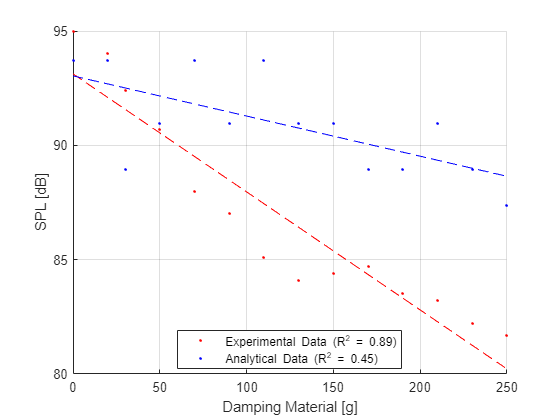

% Figure 12
f12 = figure('Name','Figure 12: MultiLevel Comparison', ...
    'NumberTitle','off');
x = Scatter(:,1);
y_1 = Scatter(:,2);
y_2 = Scatter(:,3);
y_3 = Scatter(:,4);
y_4 = Scatter(:,5);
y_5 = Scatter(:,6);
y_6 = Scatter(:,7);
y_7 = Scatter(:,8);
format long
b_1 = x\y_1;
b_2 = x\y_2;
b_3 = x\y_3;
b_4 = x\y_4;
b_5 = x\y_5;
b_6 = x\y_6;
b_7 = x\y_7;
X = [ones(length(x),1) x];
b_01 = X\y_1;
b_02 = X\y_2;
b_03 = X\y_3;
b_04 = X\y_4;
b_05 = X\y_5;
b_06 = X\y_6;
b_07 = X\y_7;
scatter(x,y_1,'r.')
hold on
scatter(x,y_2,'b.')
% plot(x,yCalc1)
ylabel('SPL [dB]')
xlabel('Damping Material [g]')
%title('Linear Regression Relation Between Accidents & Population')
grid on
yCalc1 = X*b_01;
yCalc2 = X*b_02;
yCalc3 = X*b_03;
yCalc4 = X*b_04;
yCalc5 = X*b_05;
yCalc6 = X*b_06;
yCalc7 = X*b_07;
plot(x,yCalc1,'r--')
plot(x,yCalc2,'b--')
hold off
legend('Experimental Data (R^2 = 0.89)','Analytical Data (R^2 = 0.45)','Location','best');

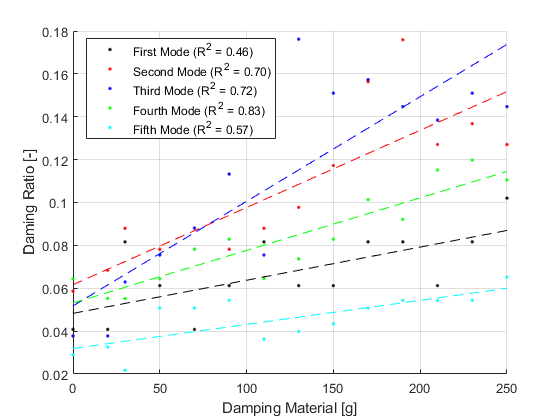

scatter(x,y_3,'k.')
hold on
scatter(x,y_4,'r.')
scatter(x,y_5,'b.')
scatter(x,y_6,'g.')
scatter(x,y_7,'c.')
ylabel('Daming Ratio [-]')
xlabel('Damping Material [g]')
grid on
plot(x,yCalc3,'k--')
plot(x,yCalc4,'r--')
plot(x,yCalc5,'b--')
plot(x,yCalc6,'g--')
plot(x,yCalc7,'c--')
hold off
legend('First Mode (R^2 = 0.46)','Second Mode (R^2 = 0.70)','Third Mode (R^2 = 0.72)','Fourth Mode (R^2 = 0.83)','Fifth Mode (R^2 = 0.57)','Location','best');

Rsq1 = 1 - sum((y_1 - yCalc1).^2)/sum((y_1 - mean(y_1)).^2);
Rsq2 = 1 - sum((y_2 - yCalc2).^2)/sum((y_2 - mean(y_2)).^2);
Rsq3 = 1 - sum((y_3 - yCalc3).^2)/sum((y_3 - mean(y_3)).^2);
Rsq4 = 1 - sum((y_4 - yCalc4).^2)/sum((y_4 - mean(y_4)).^2);
Rsq5 = 1 - sum((y_5 - yCalc5).^2)/sum((y_5 - mean(y_5)).^2);
Rsq6 = 1 - sum((y_6 - yCalc6).^2)/sum((y_6 - mean(y_6)).^2);
Rsq7 = 1 - sum((y_7 - yCalc7).^2)/sum((y_7 - mean(y_7)).^2);